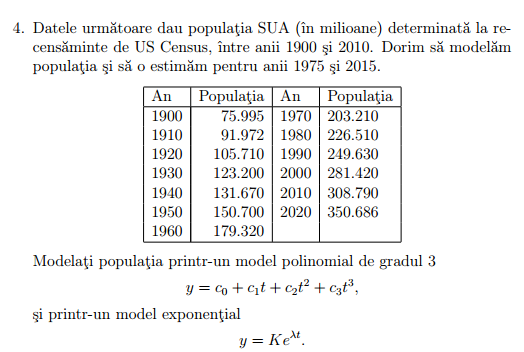

Pentru a lucra cu numere mai mici, vom prelucra anii (timpul) cu an - 1900, avand in vedere ca rezutlate sunt din 10 in 10.

years = [1900:10:2020];

t = years - 1900;
population = [75.995 91.272 105.710 123.200 131.670 150.700 179.320 203.210 226.510 249.630 281.420 308.790 350.686];

t_target = [1975 - 1900; 2015 - 1900];
years_target = [1975; 2015];

% 3rd degree Polynomial
poly3_base = poly_base(3);
poly_fit_all = least_squares(t, population, poly3_base, t);
poly_pred = least_squares(t, population, poly3_base, t_target);

% Exponential
log_population = log(population);
exp_fit_all = exp(least_squares(t, log_population, @exp_base, t));
exp_pred = exp(least_squares(t, log_population, @exp_base, t_target));

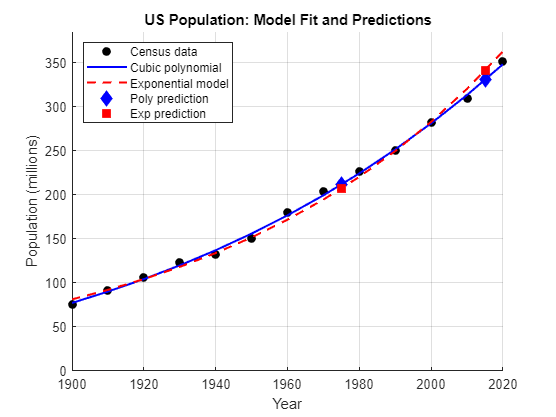

figure;
hold on;

% Original data
plot(years, population, 'ko', 'MarkerFaceColor', 'k', 'DisplayName', 'Census data');

% Fitted models
plot(years, poly_fit_all, 'b-', 'LineWidth', 1.5, 'DisplayName', 'Cubic polynomial');
plot(years, exp_fit_all, 'r--', 'LineWidth', 1.5, 'DisplayName', 'Exponential model');

% Predictions (highlighted)
plot(years_target, poly_pred, 'bd', 'MarkerSize', 8, 'MarkerFaceColor', 'b', 'DisplayName', 'Poly prediction');
plot(years_target, exp_pred, 'rs', 'MarkerSize', 8, 'MarkerFaceColor', 'r', 'DisplayName', 'Exp prediction');

% Formatting
legend('Location', 'northwest');
xlabel('Year');
ylabel('Population (millions)');
title('US Population: Model Fit and Predictions');
grid on;
xlim([1900 2020]);
all_values = [population, poly_pred(:)', exp_pred(:)'];
ylim([0, max(all_values) * 1.1]);